% GNSS signals, reconstructed carrier frequency, Doppler shifts
% D. Gailius 2020
Tx=9.02 % h analysis time (birthday Tx=M.dd   ???)

Tx = 9.0200

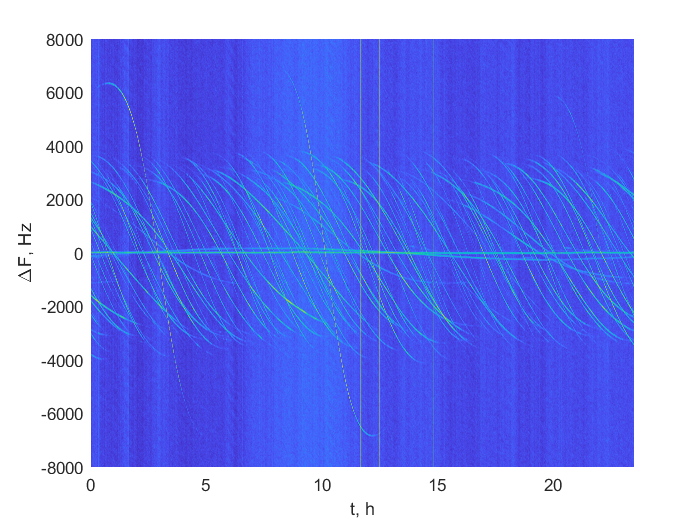


load('VDU_201006.mat'); Fcorr=720; %Hz
fL1=1575.42; %MHz (10.23 MHz × 154), GNSS L! frequency
Fs=2.048E6; % sampling frequency
t=X(1,:)/3600;
dF=Y(:,1);
dF=dF-Fcorr; % for the LO frequency correction in the receiver
Vr=dF/(fL1*1E6)*3E8; % relative speed to receiver

N1=1000;
ZdB=10*log10(Z); % A in dB
M1=min(min(ZdB(5:N1,:))); M2=max(max(ZdB(5:N1,:)));
%% ploting
figure(1);

surf(t,dF,ZdB'); view(0,90); 
shading('interp');
set(gca,'Clim',[M1,M2])
set(gca,'Xlim',[min(t),max(t)], 'Ylim',[-8000, 8000])

xlabel('t, h'); ylabel('\DeltaF, Hz')

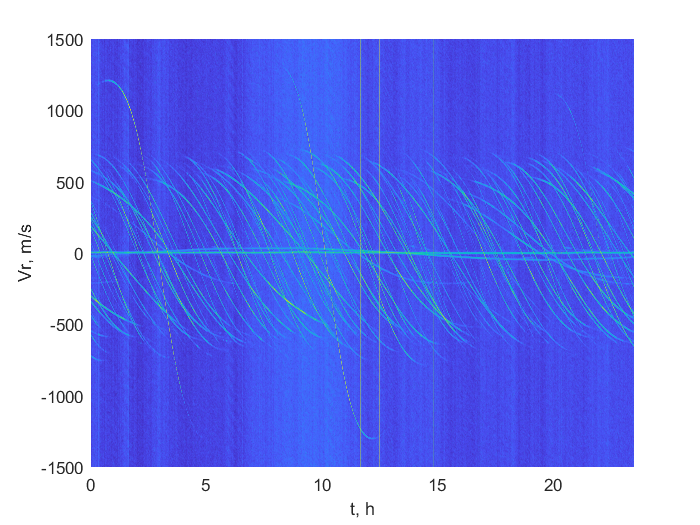


figure(2);

surf(t,Vr,ZdB'); view(0,90); 
shading('interp');
set(gca,'Clim',[M1,M2])
set(gca,'Xlim',[min(t),max(t)], 'Ylim',[-1500, 1500])

xlabel('t, h');
ylabel('Vr, m/s')


%% plot A vs dF and Vr @ selected time

I=find(t>=Tx);
I=I(1)

I = 1624

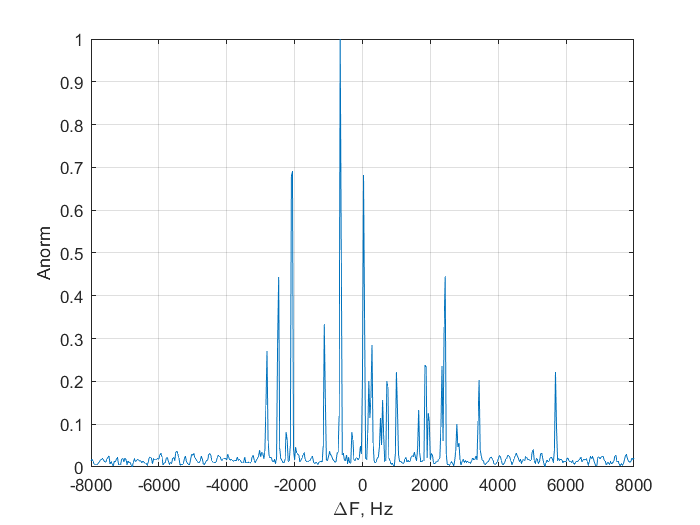

An=Z(I,:); An=An-min(An); An=An/max(An);
figure(3);
plot(dF, An)
grid on;
ylabel('Anorm'); xlabel('\DeltaF, Hz')
set(gca,'Xlim',[-8000, 8000])

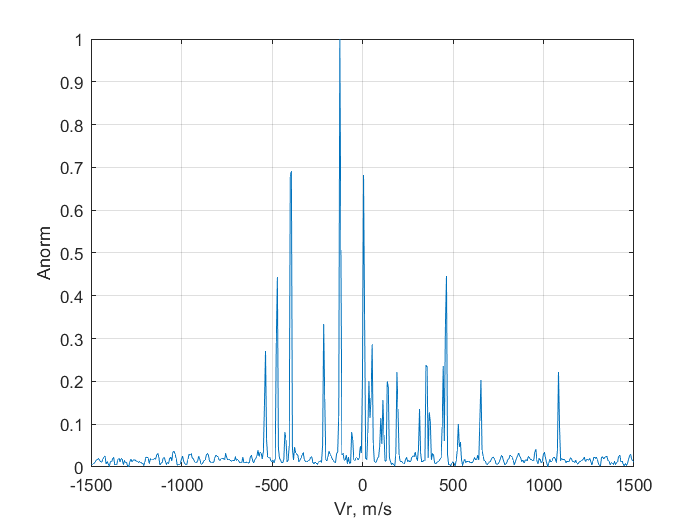


figure(4);
plot(Vr, An)
grid on;
ylabel('Anorm'); xlabel('Vr, m/s')
set(gca,'Xlim',[-1500, 1500])